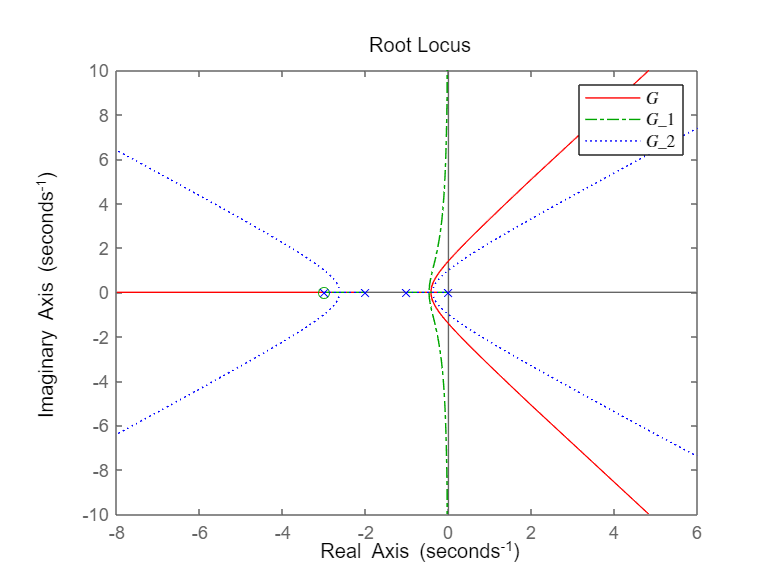

clc;
close all;
clear all;

s = tf('s');
G = 1/(s*(s+1)*(s+2));

G1 = G*(s+3);
G2 = G/(s+3);

rlocus(G,'r-',G1,'g-.',G2,'b:');
hh = legend('$G$','$G_1$','$G_2$');
set(hh,'Interpreter','latex'); 

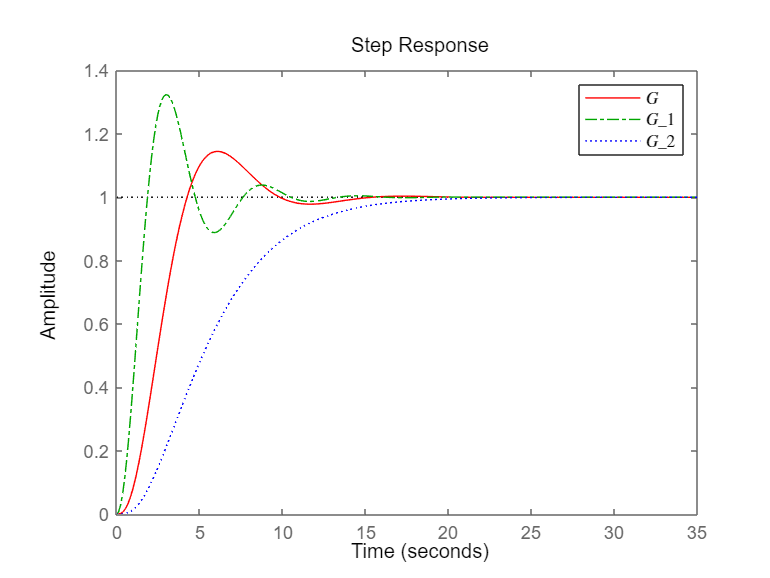


K = 1;
H  = feedback(G,K);
H1 = feedback(G1,K);
H2 = feedback(G2,K);

figure;
step(H,'r-',H1,'g-.',H2,'b:');
hh = legend('$G$','$G_1$','$G_2$');
set(hh,'Interpreter','latex'); 

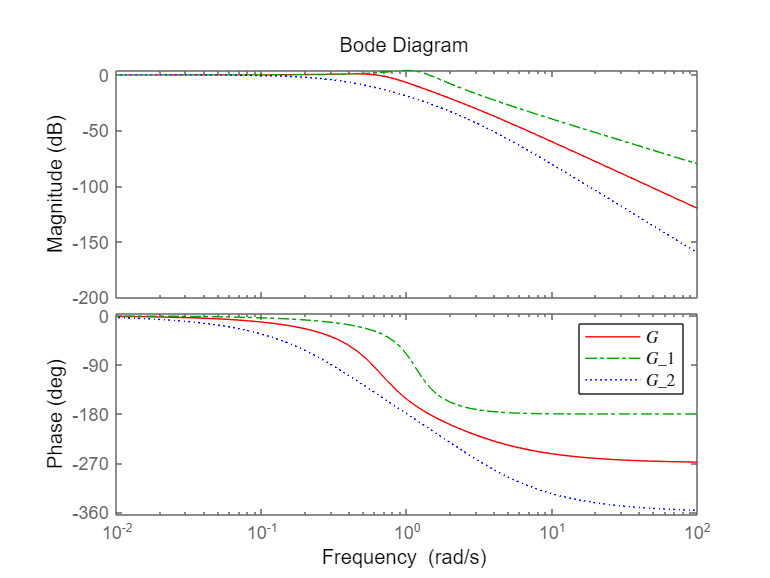

figure;
bode(H,'r-',H1,'g-.',H2,'b:');
hh = legend('$G$','$G_1$','$G_2$');
set(hh,'Interpreter','latex'); 

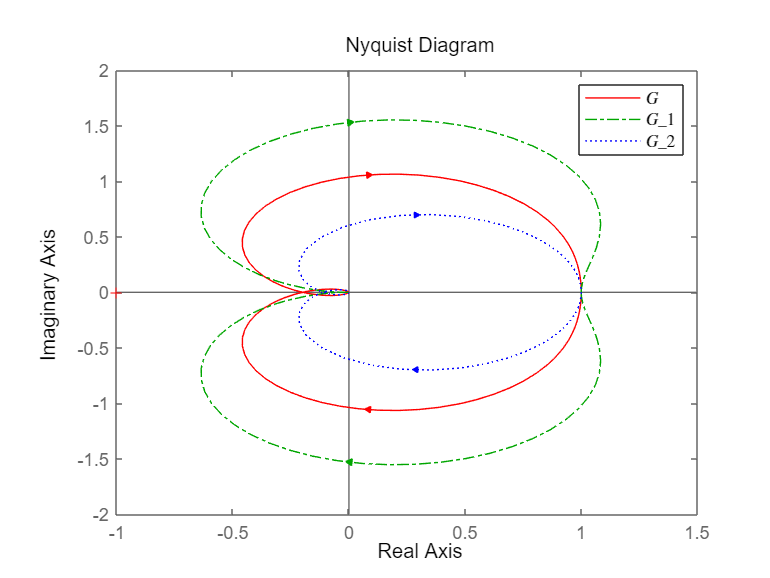

figure;
nyquist(H,'r-',H1,'g-.',H2,'b:');
hh = legend('$G$','$G_{1}$','$G_{2}$');
set(hh,'Interpreter','latex'); 